# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre:**

**Fecha:**

# Tema 4. Ejercicio 2. Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de todos los objetos de una imagen y utilizar sólo las componentes más significativas de cada objeto para reconstruirlos.

Step 1) Read Image

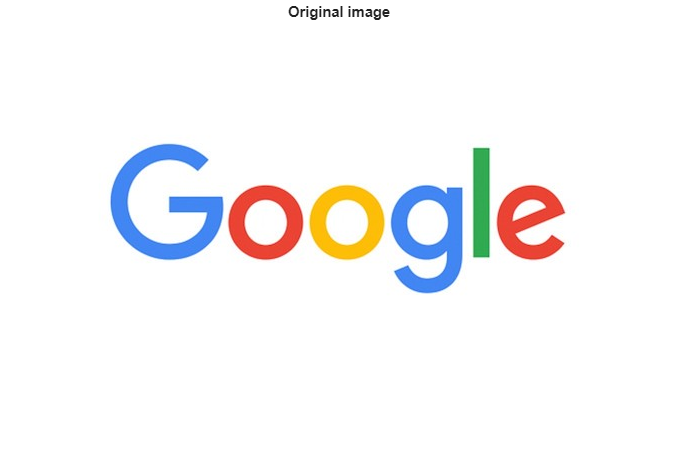

        close all
        clear all
    
        imgOriginal = imread('google.jpg');
        figure;
        imshow(imgOriginal);
        title('Original image');

Step 2) Threshold the Image

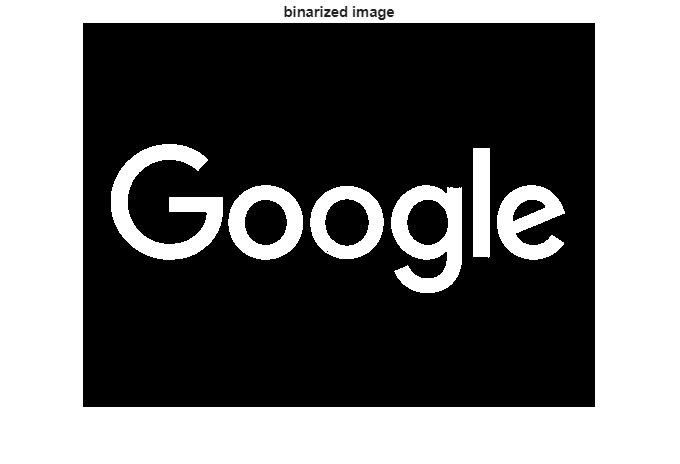

        if size(imgOriginal,3) == 3
            imgOriginal = rgb2gray(imgOriginal); 
        end
        imgBW = imbinarize(imgOriginal);
        imgBW = imcomplement(imgBW);
        
        figure;
        imshow(imgBW);
        title('binarized image');

Step 4) Find the external Boundaries

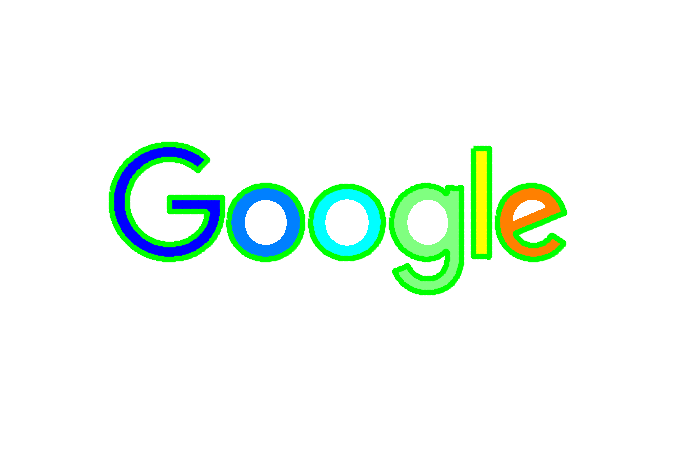

        [B,L] = bwboundaries(imgBW,'noholes');
        figure
        imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
        hold on
        for k = 1:length(B)
           boundary = B{k};
           plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
        end  

Step 5)  Fourier transform 

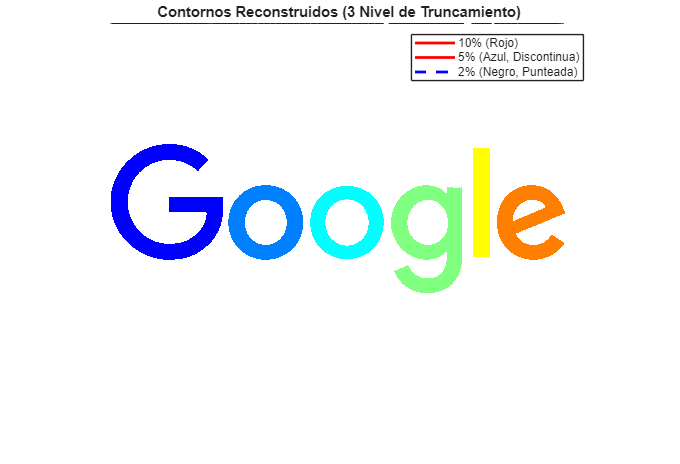

         
       % Paso 1, 2, 4 (asumidos del enunciado, ejecutados en MATLAB)

%-------------------------------------------------------------------------
% PASO 5) TRANSFORMADA Y RECONSTRUCCIÓN
%-------------------------------------------------------------------------

% Inicializa la figura sobre la que dibujaremos los contornos reconstruidos
figure;
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
title('Contornos Reconstruidos (3 Nivel de Truncamiento)');
hold on;

% Nivel de truncamiento a probar
porcentajes = [10, 5, 2];
colores = {'r', 'b', 'k'}; % Rojo, Azul, Negro para 10%, 5%, 2% respectivamente

for k = 1:length(B)
    boundary = B{k};
    
    % 1. Calcular la Transformada de Fourier (F)
    F = fourier_transform(boundary);
    N = length(F); % Longitud del contorno y número total de coeficientes
    
    for i = 1:length(porcentajes)
        P = porcentajes(i);
        M = round(N * (P / 100)); % Número de componentes a usar

        % Asegurarse de que M es al menos 1 para usar el coeficiente DC
        if M == 0
            M = 1;
        end
        
        % 2. Calcular la Transformada Inversa (reconstrucción)
        z_rec = fourier_inv_transform(F, M);
        
        % 3. Extraer coordenadas (x_rec, y_rec) de la reconstrucción compleja
        x_rec = real(z_rec);
        y_rec = imag(z_rec);
        
        % 4. Dibujar el contorno reconstruido
        % (Se dibuja solo una vez para evitar saturación visual)
        if i == 1 % Dibujar el contorno reconstruido al 10% (Rojo)
            plot(x_rec, y_rec, colores{i}, 'LineWidth', 2);
            texto = sprintf('P%d (10%%)', k);
            % text(x_rec(1), y_rec(1), texto, 'Color', 'r'); % Opcional: etiquetar
        elseif i == 2 % Dibujar el contorno reconstruido al 5% (Azul)
            plot(x_rec, y_rec, colores{i}, 'LineWidth', 2, 'LineStyle', '--');
            texto = sprintf('P%d (5%%)', k);
        elseif i == 3 % Dibujar el contorno reconstruido al 2% (Negro)
            plot(x_rec, y_rec, colores{i}, 'LineWidth', 2, 'LineStyle', ':');
            texto = sprintf('P%d (2%%)', k);
        end
    end
end
hold off;

% Agregar leyenda para facilitar la comparación
legend('10% (Rojo)', '5% (Azul, Discontinua)', '2% (Negro, Punteada)');  

Se pide: 

- Complete el paso 5, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier de cada uno de los objetos etiquetados.

- Obtenga los contornos reconstruidos de los objetos etiquetados realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Visualice los comentarios de la función para realizar la reconstrucción utilizando solamente el 10**%** del total de las componentes. Dibuje el contorno recuperado sobre la figura original utilizando hold on y compruebe si el contorno se ajusta a las letras de la imagen. 

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 5**%** del total**.**

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 2**%** del total

- Compare los resultados de los puntos 2. 3. y 4. y explique sus conclusiones. 